# **Week 7 : 16-QAM in AWGN Channel**

The code below investigates the variation of the bit error rate (BER) with the signal-to-noise ratio (SNR) in an AWGN channel when 16QAM is used

## **Transmitter**

### Modulation

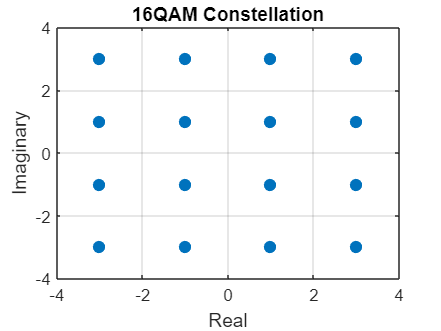

k = 4

symbols =   -3.0000 + 3.0000i  -3.0000 + 1.0000i  -3.0000 - 3.0000i  -3.0000 - 1.0000i  -1.0000 + 3.0000i  -1.0000 + 1.0000i  -1.0000 - 3.0000i  -1.0000 - 1.0000i   3.0000 + 3.0000i   3.0000 + 1.0000i   3.0000 - 3.0000i   3.0000 - 1.0000i   1.0000 + 3.0000i   1.0000 + 1.0000i   1.0000 - 3.0000i   1.0000 - 1.0000i


clear all; clearvars;

% Modulation parameters
M = 16; % Modulation order

% Visualising constellation
[k, symbols] = PlotConstellation("16QAM", 0) 


% Generating random bit sequence(s)
NSymb = 500000; % No. of symbols 
SpS = 2; % Samples per symbol
Rs = 50e9; % Symbol rate in symbols/sec
NSequences = 15; % No. of bit sequences

sourceBits = randi([0 1], NSymb*k, NSequences) % Matrix of source bits

sourceBits =      0     0     0     0     0     1     0     0     0     0     0     0     0     0     0
     0     1     0     0     1     1     1     1     1     0     0     0     0     1     1
     0     0     0     0     1     1     1     0     1     0     1     1     0     0     0
     1     0     1     0     0     1     1     1     1     0     1     0     1     0     1
     0     1     1     0     0     1     1     0     1     1     1     1     0     1     0
     0     1     1     1     1     1     0     1     1     1     0     1     1     1     1
     0     1     1     1     0     0     1     1     1     0     1     1     1     0     0
     1     0     0     0     1     0     0     0     1     0     1     1     0     0     1
     1     0     0     1     1     1     0     0     1     0     1     0     0     1     1
     1     1     0     1     1     1     0     0     1     0     1     0     1     1     1


sourceInts = bit2int(sourceBits, k)

sourceInts =      1     4     1     0     6    15     7     5     7     0     3     2     1     4     5
     1    14    14     6     5    12    10     6    15    12    11    15     6    12     5
    13     4     0    15    15    13     0     0    12     1    12     0     7    14    13
     9    15    10    14     0    14    10    10    11     7     9    15     2     3     0
     1     3     4    13    14     2    11     9    10    11     7     3    15    15     4
     1    10     4     9    10     2     1     1     2     6    12    10     0     4    15
    13     2     9     9     2    12    12    11    15    13     1    15    12     5     6
     0    11    15     4    11     7    10     5     9     1    10    14    14    11    15
    15    11     4     2     0     4    13     2     1     2    10     4    13     5    15
    12    13     9    15     7     1     3    10     4     7    15     7     0     0    11


sourceSymbols = qammod(sourceInts, M) % Maps source bit vector to symbol vector

sourceSymbols =   -3.0000 + 1.0000i  -1.0000 + 3.0000i  -3.0000 + 1.0000i  -3.0000 + 3.0000i  -1.0000 - 3.0000i   1.0000 - 1.0000i  -1.0000 - 1.0000i  -1.0000 + 1.0000i  -1.0000 - 1.0000i  -3.0000 + 3.0000i  -3.0000 - 1.0000i  -3.0000 - 3.0000i  -3.0000 + 1.0000i  -1.0000 + 3.0000i  -1.0000 + 1.0000i
  -3.0000 + 1.0000i   1.0000 - 3.0000i   1.0000 - 3.0000i  -1.0000 - 3.0000i  -1.0000 + 1.0000i   1.0000 + 3.0000i   3.0000 - 3.0000i  -1.0000 - 3.0000i   1.0000 - 1.0000i   1.0000 + 3.0000i   3.0000 - 1.0000i   1.0000 - 1.0000i  -1.0000 - 3.0000i   1.0000 + 3.0000i  -1.0000 + 1.0000i
   1.0000 + 1.0000i  -1.0000 + 3.0000i  -3.0000 + 3.0000i   1.0000 - 1.0000i   1.0000 - 1.0000i   1.0000 + 1.0000i  -3.0000 + 3.0000i  -3.0000 + 3.0000i   1.0000 + 3.0000i  -3.0000 + 1.0000i   1.0000 + 3.0000i  -3.0000 + 3.0000i  -1.0000 - 1.0000i   1.0000 - 3.0000i   1.0000 + 1.0000i
   3.0000 + 1.0000i   1.0000 - 1.0000i   3.0000 - 3.0000i   1.0000 - 3.0000i  -3.0000 + 3.0000i   1.0000 - 3.0000i   3.0000 - 


% 16QAM mapping

sourceSymbolsUpsampled = repelem(sourceSymbols, SpS, 1)

sourceSymbolsUpsampled =   -3.0000 + 1.0000i  -1.0000 + 3.0000i  -3.0000 + 1.0000i  -3.0000 + 3.0000i  -1.0000 - 3.0000i   1.0000 - 1.0000i  -1.0000 - 1.0000i  -1.0000 + 1.0000i  -1.0000 - 1.0000i  -3.0000 + 3.0000i  -3.0000 - 1.0000i  -3.0000 - 3.0000i  -3.0000 + 1.0000i  -1.0000 + 3.0000i  -1.0000 + 1.0000i
  -3.0000 + 1.0000i  -1.0000 + 3.0000i  -3.0000 + 1.0000i  -3.0000 + 3.0000i  -1.0000 - 3.0000i   1.0000 - 1.0000i  -1.0000 - 1.0000i  -1.0000 + 1.0000i  -1.0000 - 1.0000i  -3.0000 + 3.0000i  -3.0000 - 1.0000i  -3.0000 - 3.0000i  -3.0000 + 1.0000i  -1.0000 + 3.0000i  -1.0000 + 1.0000i
  -3.0000 + 1.0000i   1.0000 - 3.0000i   1.0000 - 3.0000i  -1.0000 - 3.0000i  -1.0000 + 1.0000i   1.0000 + 3.0000i   3.0000 - 3.0000i  -1.0000 - 3.0000i   1.0000 - 1.0000i   1.0000 + 3.0000i   3.0000 - 1.0000i   1.0000 - 1.0000i  -1.0000 - 3.0000i   1.0000 + 3.0000i  -1.0000 + 1.0000i
  -3.0000 + 1.0000i   1.0000 - 3.0000i   1.0000 - 3.0000i  -1.0000 - 3.0000i  -1.0000 + 1.0000i   1.0000 + 3.0000i   

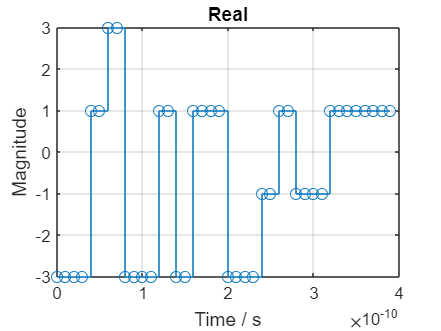


T = 1/(SpS*Rs); % Sampling period in s
t= [0:1:NSymb*SpS - 1]*T; % Time vector for plotting time-series data

% Visualising symbols
stairs(t(1:20*SpS), real(sourceSymbolsUpsampled(1:20*SpS,1)), "o-");
title("Real")
xlabel("Time / s")
ylabel("Magnitude")
grid on

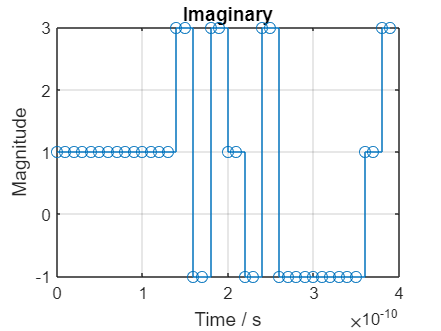


stairs(t(1:20*SpS), imag(sourceSymbolsUpsampled(1:20*SpS,1)), "o-");
title("Imaginary")
xlabel("Time / s")
ylabel("Magnitude")
grid on

### Adding AWGN

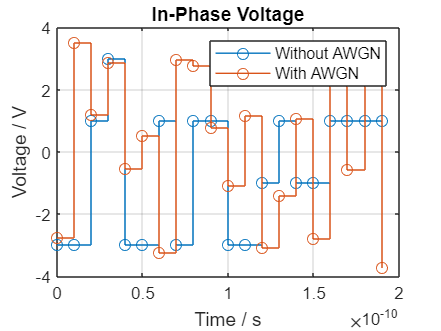

% Adding AWGN to the voltage waveforms before pulse shaping

SNRb_dB = [0:NSequences-1]'; % SNR per bit in dB
powerPerSymb = mean(abs(symbols).^2);
powerPerBit= powerPerSymb/k;

sourceSymbols_AWGN = zeros(size(sourceSymbols)); % Noisy signal to be shaped 
for i=1:NSequences
    SNRb_Lin(i,1) = 10^(SNRb_dB(i,1)/10); % linear SNR per symbol
    % AWGN_StdDev(i,1) = sqrt(0.5*powerPerSymb/SNRb_Lin(i,1)); % AWGN Standard deviation
    % sourceSymbols_AWGN(:,i) = sourceSymbols(:,i) + (1/sqrt(2))*(AWGN_StdDev(i,1)*randn(size(sourceSymbols,1),1) + 1i*AWGN_StdDev(i,1)*randn(size(sourceSymbols,1),1));
    sourceSymbols_AWGN(:,i) = awgn(sourceSymbols(:,i), convertSNR(SNRb_dB(i),'ebno', samplespersymbol=1, bitspersymbol=k), powerPerSymb);
end


% Debugging AWGN addition
% Visualising symbol variation with time with and without AWGN
stairs(t(1:10*SpS), real(sourceSymbols(1:10*SpS,1)), '-o');
hold on 
stairs(t(1:10*SpS), real(sourceSymbols_AWGN(1:10*SpS,11)), '-o');
title("In-Phase Voltage");
xlabel("Time / s");
ylabel("Voltage / V");
legend("Without AWGN", "With AWGN");
grid on
hold off

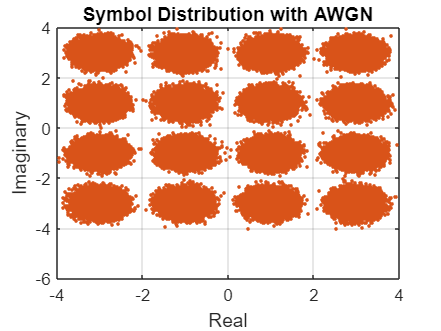


% Visualising symbol distribution with and without noise 
plot(symbols, '+', MarkerSize=4);
hold on
plot(sourceSymbols_AWGN(:,15), '.');
title("Symbol Distribution with AWGN");
xlabel("Real");
ylabel("Imaginary");
grid on
hold off


% Premature decoding to check validity of AWGN model
% tempInts = pskdemod(vUpsampled_AWGN, M);
% tempBits = int2bit(tempInts, k);
% 
% for i=1:NSequences
%     [~, tempBER(i,1)] = biterr(sourceBits(:,i), downsample(tempBits(:,i), SpS));
% end
% 
% % Visualising BER vs SNR plot
% semilogy(SNRb_dB(1:11), 0.5*erfc(sqrt(10.^(SNRb_dB(1:11)/10))));
% hold on
% semilogy(SNRb_dB, tempBER, "-o");
% title("BER vs SNR");
% xlabel("SNR per bit / dB");
% ylabel("BER");
% legend("Theoretical", "Simulation")
% grid on
% hold off



### Pulse Shaping

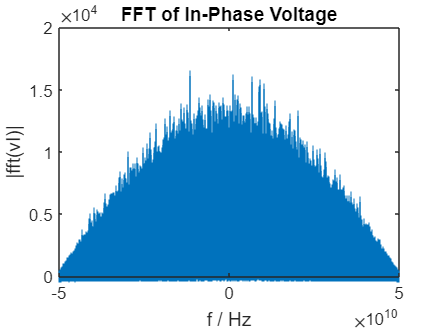

% Frequency spectrum of voltage waveform before filtering
fft_vI = fftshift(fft(sourceSymbolsUpsampled(:,15))); % FFT without AWGN
freqArr = [-NSymb*SpS/2:NSymb*SpS/2 - 1]/(T*NSymb*SpS);
stem(freqArr, abs(fft_vI), "|");
title("FFT of In-Phase Voltage");
xlabel("f / Hz");
ylabel("|fft(vI)|");

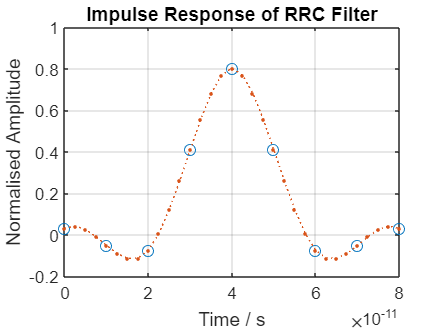


% RRC filter
filterSpan = 4; % Span of RRC filter in no. of symbols
rollOff = 0.5;
filterResponse = rcosdesign(rollOff, filterSpan, SpS)';

% Visualisation of RRC filter
filterResponse_t = [0:1:filterSpan*SpS]*T; % time vector for the filter response
filterResponse_t_interp = [0:0.25:filterSpan*SpS]*T;
filterResponse_interp = interp1(filterResponse_t, filterResponse, filterResponse_t_interp, "spline");
plot(filterResponse_t, filterResponse, "o", filterResponse_t_interp, filterResponse_interp, ":.");
title('Impulse Response of RRC Filter');
xlabel('Time / s');
ylabel('Normalised Amplitude');
grid on

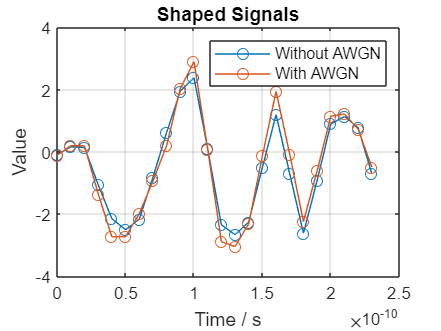


% Using RC filter to shape vI and vQ
% Without AWGN
sourceSymbols_shaped = upfirdn(sourceSymbols, filterResponse, SpS, 1);
% With AWGN
sourceSymbols_shaped_AWGN = upfirdn(sourceSymbols_AWGN, filterResponse, SpS, 1); 


% Visualising pulse-shaped voltages
samples = 1+(NSymb-1)*SpS + filterSpan*SpS;
sourceSymbols_shaped_t = [0:1:samples-1]*T;
plot(sourceSymbols_shaped_t(1:10*SpS + filterSpan), real(sourceSymbols_shaped(1:10*SpS + filterSpan,1)), "o-");
hold on
plot(sourceSymbols_shaped_t(1:10*SpS + filterSpan), real(sourceSymbols_shaped_AWGN(1:10*SpS + filterSpan,1)), "o-");
title("Shaped Signals");
ylabel("Value");
xlabel('Time / s');
legend("Without AWGN", "With AWGN");
grid on
hold off

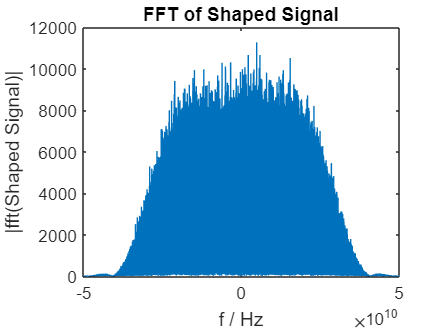


% Frequency spectrum of voltage waveform after filtering
fft_sourceSymbols_shaped = fftshift(fft(sourceSymbols_shaped(:,1)));
freqArr = [-samples/2:samples/2 - 1]/(T*samples);
plot(freqArr, abs(fft_sourceSymbols_shaped));
title("FFT of Shaped Signal");
xlabel("f / Hz");
ylabel("|fft(Shaped Signal)|");
hold off


bandwidth = 0.5*(1+rollOff)/T

bandwidth = 7.5000e+10


% Eye diagram of voltage waveform before filtering
% eyediagram(vI(1:1000,1), SpS);
% title("Eye Diagram of Discrete In-Phase Voltage")
% eyediagram(shapedVI(1:1000,1), SpS);
% title("Eye Diagram of Pulse-Shaped In-Phase Voltage")

### Matched Filtering and Downsampling

% Passing shaped signals through matched filter and downsampling
sourceSymbols_shaped_filtered = upfirdn(sourceSymbols_shaped, filterResponse, 1, SpS); sourceSymbols_shaped_filtered = sourceSymbols_shaped_filtered(filterSpan + 1:end - filterSpan,:);
sourceSymbols_shaped_AWGN_filtered = upfirdn(sourceSymbols_shaped_AWGN, filterResponse, 1, SpS); sourceSymbols_shaped_AWGN_filtered = sourceSymbols_shaped_AWGN_filtered(filterSpan + 1:end - filterSpan,:);

## DSP

### Decision and Decoding

% Decoding recieved symbols
decodedSymbols = sourceSymbols;
decodedInts = qamdemod(decodedSymbols, M);
decodedBits = int2bit(decodedInts, k);
biterr(decodedBits, sourceBits)

ans = 0


decodedSymbols_AWGN = sourceSymbols_AWGN;
decodedInts_AWGN = qamdemod(decodedSymbols_AWGN, M);
decodedBits_AWGN = int2bit(decodedInts_AWGN, k);

decodedSymbols_shaped = sourceSymbols_shaped_filtered;
decodedInts_shaped= qamdemod(decodedSymbols_shaped, M);
decodedBits_shaped = int2bit(decodedInts_shaped, k);
biterr(decodedBits_shaped, sourceBits)

ans = 0

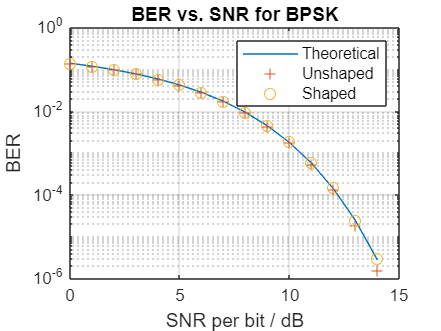


decodedSymbols_shaped_AWGN = sourceSymbols_shaped_AWGN_filtered;
decodedInts_shaped_AWGN= qamdemod(decodedSymbols_shaped_AWGN, M);
decodedBits_shaped_AWGN = int2bit(decodedInts_shaped_AWGN, k);

BER_AWGN = zeros(NSequences,1); numErrors = zeros(NSequences,1);
BER_AWGN_shaped = zeros(NSequences,1); numErrors_shaped = zeros(NSequences,1);

for i=1:NSequences
    [numErrors(i,1), BER_AWGN(i,1)] = biterr(sourceBits(:,i), decodedBits_AWGN(:,i));
    [numErrors_shaped(i,1), BER_AWGN_shaped(i,1)] = biterr(sourceBits(:,i), decodedBits_shaped_AWGN(:,i));
end

semilogy(SNRb_dB, (3/8)*erfc(sqrt(SNRb_Lin*2/5)));
hold on
semilogy(SNRb_dB, BER_AWGN, '+');
semilogy(SNRb_dB, BER_AWGN_shaped, 'o');
title("BER vs. SNR for BPSK");
ylabel("BER");
xlabel("SNR per bit / dB");
legend("Theoretical", "Unshaped", "Shaped");
grid on
hold off


% save("BPSKData.mat","SNRb_dB", "BER_BPSK")